## Simulation's parameter

clc
clearvars
close all

%% debug parameters
% spectrum debug set to 1 to select specific spectrum shapes
debugMode = 1;
spectAnalizer = 1;

% noise debug parameter, set to 0 to eliminate noise
noiseOn = 0;
% chan debug parameter: if chan = 1 ==> AWGN, if chan = 2 ==> multipath
chan = 2;



%% channel
% channel length
if chan == 1
    % AWGN
    L = 1;
else
    % multipath
    L = 10;
end

%% OFDM parameters
% Number of subcarriers
N = 64;
% CP length
NCP = 16;
% Generater FFT matrix
% single row with N elements
row = 0:N-1;
column = row.';
% NxN matrix
mat = repmat(row,N,1).*column/N;
FMat = 1/sqrt(N)*exp(-1i*2*pi*mat);
FMatChan = sqrt(N)*FMat(:,1:L);

%% Bit source
% number of simulated bits (must be a multiple of N)
nBit = 1e5*N;
% Bit rate at the source (bit/s)
rSource = 1e7;
% Bit signaling length (s)
tBit = 1/rSource;

%% Symbol mapper
% Beware: the mapper generates symbold in the frequency domain.
% Modulation format: PAM, QAM o PSK. Setting modFormat yields
% 1) M-PAM
% 2) M-QAM (in questo caso M deve essere una potenza di 2 con esponente pari)
% 3) M-PSK
modFormat = 2;
% constellation size
M = 4;
% symbol time
T = tBit*log2(M);

% Maximum EsN0 value
EsN0Max = 13;

if noiseOn == 0
    EsN0Max = 0;
end

## Variables initialization

EsN0Vect = 0:EsN0Max;
ser = zeros(length(EsN0Vect),1);
ber = zeros(length(EsN0Vect),1);
rng(1)

## Matlab objects

% Spectrum analizer
if spectAnalizer  == 1
    analizer = dsp.SpectrumAnalyzer(...
        'Name', 'Spectrum Analyzer',...
        'Title', 'Spettro inviluppo complesso',...
        'SpectrumType', 'Power density',...
        'FrequencySpan', 'Full',...
        'ShowLegend', true,...
        'SampleRate', 1/T,...
        'SpectralAverages', 100);
end

## Bit source

% bit
b = round(rand(nBit,1));

## Mapper

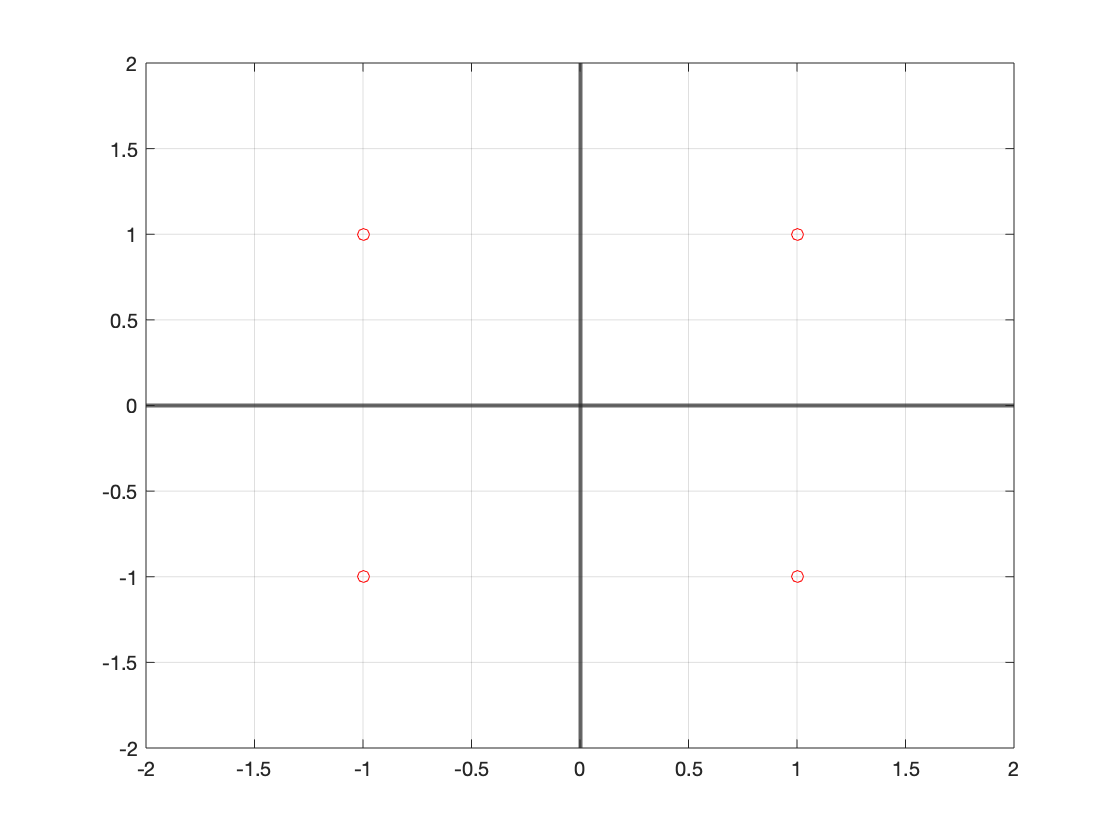

% number of transmitted symbols
nSym = nBit/log2(M);

% Map group of bits in symbol indices
symInd = bitMapper(b,M);

% symbo mapper
if modFormat == 1
    sym = pammod(symInd,M,0,'gray');
    A = (M^2-1)/3;
    
elseif modFormat == 2
    sym = qammod(symInd,M,'gray');
    A = 2*(M-1)/3;
    
elseif modFormat == 3
    sym = pskmod(symInd,M,0,'gray');
    A = 1;
end

plot(sym,'ro')
grid
if modFormat == 1
    axis([-M M -1 1])
else
    axis([-sqrt(M) sqrt(M) -sqrt(M) sqrt(M)])
end
box on
xline(0,'Linewidth',2);
xline(-2,'--');
xline(2,'--');

yline(0,'Linewidth',2);
yline(-2,'--');
yline(2,'--');


% symbols' mean square value
AEst = mean(abs(sym).^2);

## OFDM transmitter

### **1. Serial to parallel conversion**

% serial to parallel converter: the vector of symbols is divided in blocks
% of size N
symBlocks = reshape(sym,N,[]);

### **2. Time-domain converison**

if debugMode == 1
    debugVector = zeros(N,1);
    debugVector(2) = 1;
    %debugVector(2) = 1;
    %debugVector(9:end-7) = 1;
    symBlocks = symBlocks.*debugVector;
end

% The conversion to time domain is obtained by multiplying by F^H each block of N
% symbols
timeVector = FMat'*symBlocks;

### 3. CP insertion

% CP insertion
timeVectorCP = [timeVector(end-NCP+1:end,:);timeVector];
if debugMode == 1
    plot(real(timeVectorCP(:,3)))
    xline(1,'r');
    xline(NCP,'b');
    xline(N+1,'r');
    xline(N+NCP,'b');
end
% parallel to serial: the stream of time samples is ready to be transmitted
% over the channel
timeVectorSerial = reshape(timeVectorCP,1,[]);

## Channel

% generate multipath channel
[channel,meanDelay,delaySpread] = propChannel(L,chan);
stem(abs(channel))
xline(meanDelay);
xline(meanDelay+delaySpread,'r');

### 4. Propagation

% OFDM signal propagates through the channel
yVect = conv(channel,timeVectorSerial);
% eliminate the last L-1 samples
yVect(end-(L-2):end) = [];

% adjust noise dimensions
noiseVectSize = size(yVect);

for muta = 1:length(EsN0Vect)
    EsN0dB = EsN0Vect(muta);
    % generate noise
    EsN0 = 10^(EsN0dB/10);
    sigmaNoise = sqrt(A/(2*EsN0));
    noise = sigmaNoise*(randn(noiseVectSize)+1i*randn(noiseVectSize));
    sigRx = yVect+noiseOn*noise;
    

## OFDM receiver

###  5. Remove CP and serial to parallel conversion

    % reshape the sequence of samples in blocks of N+NCP elements
    r = reshape(sigRx,N+NCP,[]);
    % remove the CP part
    r(1:NCP,:) = [];
    if spectAnalizer == 1
        analizer(reshape(r,[],1))
    end

###  6. FFT

        % transform the received samples in the frequency domain
        R = FMat*r;

## Decision logic

        % channel gain on each subcarrier
        chanFreqEst = FMatChan*channel;
        % equalize the channel
        X = R./chanFreqEst;
        
        % create a serial stream of decision variables
        decVar = reshape(X,[],1);
        
        if modFormat == 1
            symDec = pamdemod(decVar,M,0,'gray');
            
        elseif modFormat == 2
            symDec = qamdemod(decVar,M,'gray');
            
        elseif modFormat == 3
            symDec = pskdemod(decVar,M,0,'gray');
        end
        bitDec = symDemap(symDec,M);
        
        % Calcolo e plotto la SER
        ser(muta) = nnz(symDec-symInd)/nSym;
        
        % Calcolo e plotto la BER
        ber(muta) = nnz(bitDec-b)/nBit;
    end
    
    %calcolo la sep teorica
    if modFormat == 1
        sep = errProbMPAM(EsN0Vect,M);
        
    elseif modFormat == 2
        sep = errProbMQAMSemp(EsN0Vect,M);
        
    elseif modFormat == 3
        sep = errProbMPSK(EsN0Vect,M);
        
    end
    
    figure
    semilogy(EsN0Vect,ser)
    title('Symbol error probability')
    hold
    semilogy(EsN0Vect,sep.')
    grid
    
    % plotto i risultati in termini bep in funzione di Eb/N0
    figure
    EbN0Vect = EsN0Vect-10*log10(log2(M));
    bep = sep/log2(M);
    semilogy(EbN0Vect,bep)
    title('Bit error probability')
    hold on
    semilogy(EbN0Vect,ber)
    
    grid
    hold off
    
    scatter(real(decVar),imag(decVar),'o')
    grid
    if modFormat == 1
        axis([-M M -1 1])
    else
        axis([-sqrt(M) sqrt(M) -sqrt(M) sqrt(M)])
    end
    box on
    xline(0,'Linewidth',2);
    xline(-2,'--');
    xline(2,'--');
    
    yline(0,'Linewidth',2);
    yline(-2,'--');
    yline(2,'--');

    function symInd = bitMapper(bit,M)
    % funzione che mappa i bit in ingresso sui simboli della
    % costellazione. L'uscita sono gli indici dei simboli della costellazione
    
    % divido il flusso in uscita dalla sorgente in gruppi di log2(M) bit
    bitReshaped = reshape(bit,[],log2(M));
    % converto ciascun gruppo di log2(M) bit in un intero compreso tra 0 e M-1
    symInd = bi2de(bitReshaped);
    end
    
    function bit = symDemap(sym,M)
    % funzione che dati gli indici dei simboli ricostruisce i bit
    % corrispondenti
    bitMat = de2bi(sym,log2(M));
    bit = reshape(bitMat,[],1);
    end